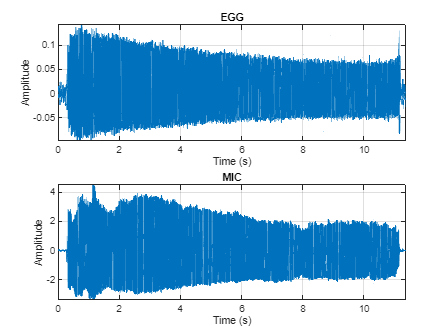

clc, clear
%% Load Data

% PF205_20180101
% This subject has corrupted egg signals
%matFile = "E:\code\fulldata\P50\PF205\W1\InLab\MAT calibrated segments\PF205_20180101_soft_a.mat";
%matFile = "E:\code\fulldata\P50\PF205\W1\InLab\MAT calibrated segments\PF205_20180101_soft_a-2.mat";
%matFile = "E:\code\fulldata\P50\PF205\W1\InLab\MAT calibrated segments\PF205_20180101_loud_a.mat";

% PF217_20180101
%matFile = "E:\code\fulldata\P50\PF217\W1\InLab\MAT calibrated segments\PF217_20180101_soft_a.mat"; % <- A lot of noise in this signal
%matFile = "E:\code\fulldata\P50\PF217\W1\InLab\MAT calibrated segments\PF217_20180101_loud_a"; 
%%%%%%%%%%%%%%%%

% NM145_20141231
% noise at 0.8 kHz 
%matFile = "E:\code\fulldata\R33\NM145\W1\InLab\MAT calibrated segments\NM145_20141231_soft_a.mat";
matFile = "E:\code\fulldata\R33\NM145\W1\InLab\MAT calibrated segments\NM145_20141231_loud_a.mat"; %<- The detection of peaks does not work here

% PF235_20180101
%matFile = "E:\code\fulldata\P50\PF235\W1\InLab\MAT calibrated segments\PF235_20180101_loud_a.mat"; 
%matFile = "E:\code\fulldata\P50\PF235\W1\InLab\MAT calibrated segments\PF235_20180101_soft_a.mat"; % <- This signal has noise
%matFile = "E:\code\fulldata\P50\PF235\W1\InLab\MAT calibrated segments\PF235_20180101_speech.mat";

% NF217_20221231

%matFile = "E:\code\fulldata\P50\NF217\W1\InLab\MAT calibrated segments\NF217_20221231_loud_a.mat"; % <- This signal is great for analysis, the GF looks good
%matFile = "E:\code\fulldata\P50\NF217\W1\InLab\MAT calibrated segments\NF217_20221231_soft_a.mat";

%matFile = "E:\code\fulldata\P50\NM281\W1\InLab\MAT calibrated segments\NM281_20210101_loud_a.mat";


data = load(matFile);
fs = data.fs;
mic = data.Mic.Data(:).';
sound = false;
if sound
    soundsc(mic, fs);
end
egg = data.EGG.Data(:)';

show_full = true;  
t_init = 0.2; t_end = 0.35; % Ax limits
plotSignals(egg, "EGG", mic, "MIC", fs, show_full, t_init, t_end)

% Get gcis from the EGG signal
[gcis, degg]= getGCIs(egg, fs);
F0 = fs/ mean(diff(gcis))

F0 = 57.2146

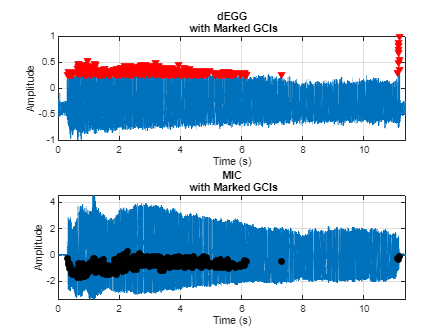

plotSignalsWithGCIs(degg, "dEGG", mic, "MIC", fs, gcis, show_full, t_init, t_end)

%To avoid missing GCIs during transition regions, start from the 'offset' and end at the last GCI minus the offset.
offset = 6;
start_idx = gcis(offset);
end_idx = gcis(end-offset-1);

degg_cut = degg(start_idx:end_idx);
mic_cut = mic(start_idx:end_idx);
gcis_cut = gcis(gcis >= start_idx & gcis <= end_idx) - start_idx + 1;

function tmarks = make_tmarks(s, fs, frame_len_ms, frame_shift_ms)
    frame_len = round(frame_len_ms / 1000 * fs);  
    frame_shift = round(frame_shift_ms / 1000 * fs);

    N = length(s);
    starts = 1:frame_shift:(N - frame_len + 1);
    ends = starts + frame_len - 1;

    tmarks = [starts; ends];
end

% Compute QCP
VTorder   = 20;
GSorder   = 3;
lipRad    = 0.99;
DQ=0.7;PQ=0.1;RQ=0.14;
causality = 'causal';
STcompens = 0;    % 0 = OFF, 1 = ON
%tmarks = make_tmarks(mic_cut, fs, 32, 16); 
%tmarks = make_tmarks(mic_cut, fs, round(10*T_seconds*1000),  round(5*T_seconds*1000));
tmarks = make_tmarks(mic_cut, fs, round(10*1000/F0),  round(5*1000/F0));

tic
[G, dG, ~, ~] = qcp_olaf(mic_cut, fs, VTorder, GSorder, lipRad, DQ, PQ, RQ, causality, STcompens, tmarks, gcis_cut);
fprintf('Execution time: %.6f seconds\n', toc);

Execution time: 11.313436 seconds


## Analysis of the resulting glottal flow

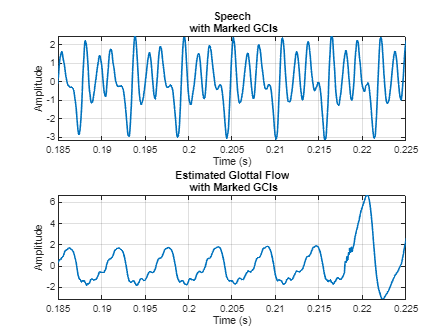

show_full = false;  
t_init = 0.185; t_end = 0.225; 
plotSignalsWithGCIs(mic_cut, "Speech", G, "Estimated Glottal Flow", fs, gcis_cut, show_full, t_init, t_end)

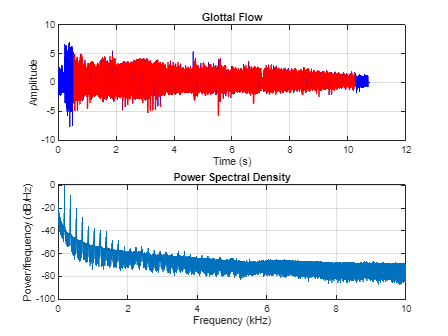

startPercentage = 0.05;
endPercentage = 0.95;
plotPwelch(G,"Glottal Flow", fs, startPercentage, endPercentage)

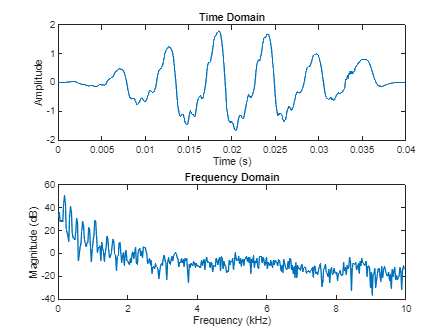

use_time = true;
if use_time
    t_init = 0.185; t_end = 0.225;
    start_idx = round(t_init * fs); end_idx = round(t_end * fs);
else
    start_idx = 1;
    end_idx = round(0.06 * fs);
end

segment = G(start_idx:end_idx);
w = hann(length(segment));
segment_windowed = segment(:) .* w;

plotFFT(segment_windowed, fs);

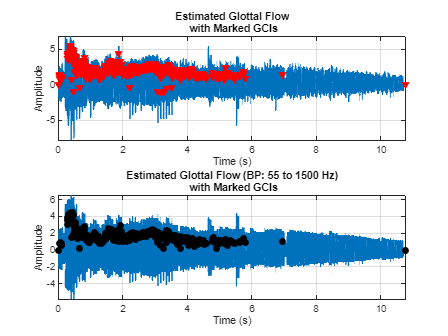

% Post processing 
function [y,b] = zeroDelayFIR(x, fs, F0)
N = 1024;
f_low = max(50, 0.9 * F0);
f_high = min(fs/2, F0 * 6 * 1.2);  
b = fir1(N, [f_low f_high]/(fs/2), 'bandpass');
y = filtfilt(b, 1, x);
end

[fG,b] = zeroDelayFIR(G, fs, F0);
%figure;
%freqz(b, 1, 1024, fs);

show_full = true;  
t_init = 0.185; t_end = 0.225;
plotSignalsWithGCIs(G, "Estimated Glottal Flow", fG, "Estimated Glottal Flow (BP: 55 to 1500 Hz)", fs, gcis_cut, show_full, t_init, t_end)

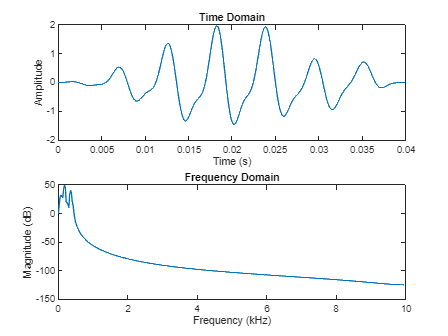

segment = fG(start_idx:end_idx);
w = hann(length(segment));
segment_windowed = segment(:) .* w;
plotFFT(segment_windowed, fs);

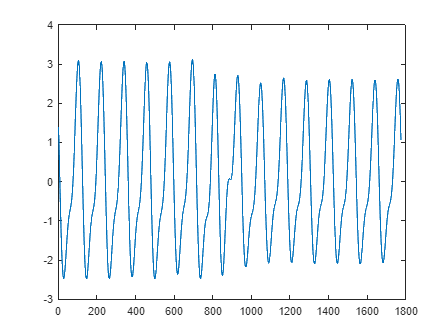

% Segment analysis to discard to train with good glottal flow 

start_idx = gcis_cut(51+48); 
end_idx = gcis_cut(51+56); 

%start_idx = gcis_cut(51-48); 
%end_idx = gcis_cut(51-40); 

%start_idx = gcis_cut(51-32); 
%end_idx = gcis_cut(51-24); 

%start_idx = gcis_cut(51-8); 
%end_idx = gcis_cut(51); 

%start_idx = 3962; % gcis_cut(51)
%end_idx = 4499; % gcis_cut(58)

gci_in_window = gcis_cut(gcis_cut >= start_idx & gcis_cut <= end_idx);
segment = fG(start_idx:end_idx);
figure;
plot(segment)

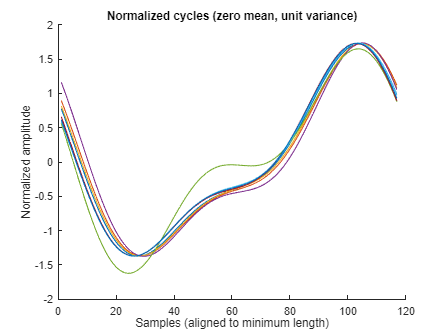

num_cycles = length(gci_in_window) - 1;
cycles = cell(1, num_cycles);
for i = 1:num_cycles
    c_start = gci_in_window(i);
    c_end = gci_in_window(i+1) - 1;
    if c_end > length(fG)
        continue;
    end
    cycles{i} = fG(c_start:c_end);
end

figure;
hold on;
title('Normalized cycles (zero mean, unit variance)');
xlabel('Samples (aligned to minimum length)');
ylabel('Normalized amplitude');

min_len = min(cellfun(@length, cycles));

for i = 1:num_cycles
    x = cycles{i}(1:min_len);
    x = (x - mean(x)) / std(x);
    plot(x, 'LineWidth', 1);
end

hold off;

% DTW aligns two signals by non-linearly stretching or compressing them 
% in time to find the minimum distance between their shapes, 
% making it useful for comparing patterns that vary in duration or timing.

dtw_distances = [];
for i = 1:num_cycles
    for j = i+1:num_cycles
        x = cycles{i};
        y = cycles{j};
        
        % Asegúrate de que ambos ciclos no estén vacíos
        if isempty(x) || isempty(y)
            continue;
        end

        min_len = min(length(x), length(y));
        x = x(1:min_len);
        y = y(1:min_len);

        x = (x - mean(x)) / std(x);
        y = (y - mean(y)) / std(y);

        % Calcula la distancia DTW (usa la función de MATLAB)
        d = dtw(x, y);
        dtw_distances(end+1) = d;
    end
end

avg_dtw_dist = mean(dtw_distances);
disp(['Average DTW distance between cycles in this window: ', num2str(avg_dtw_dist)]);

Average DTW distance between cycles in this window: 3.3619


window_duration = 0.04; 
window_length = round(window_duration * fs);
dtw_threshold = 3.5; 

num_windows = floor(length(fG) / window_length);
accepted_indices = []; 
avg_dtw_all = NaN(1, num_windows); 

for i = 1:num_windows
    start_idx = (i - 1) * window_length + 1;
    end_idx = start_idx + window_length - 1;
    if end_idx > length(fG)
        break;
    end
    
    segment = fG(start_idx:end_idx);
    gci_in_window = gcis_cut(gcis_cut >= start_idx & gcis_cut <= end_idx);
    if length(gci_in_window) < 3
        continue;
    end

    num_cycles = length(gci_in_window) - 1;
    cycles = cell(1, num_cycles); 
    for k = 1:num_cycles
        c_start = gci_in_window(k);
        c_end = gci_in_window(k+1) - 1;
        if c_end > length(fG)
            continue;
        end
        cycles{k} = fG(c_start:c_end);
    end

    dtw_distances = [];
    for m = 1:num_cycles
        for n = m+1:num_cycles
            x = cycles{m};
            y = cycles{n};
            if isempty(x) || isempty(y)
                continue;
            end

            min_len = min(length(x), length(y));
            x = x(1:min_len);
            y = y(1:min_len);
         
            x = (x - mean(x)) / std(x);
            y = (y - mean(y)) / std(y);

            d = dtw(x, y);
            dtw_distances(end+1) = d;
        end
    end

     if isempty(dtw_distances)
        continue;
    end

    avg_dtw = mean(dtw_distances);
    avg_dtw_all(i) = avg_dtw;

    if avg_dtw < dtw_threshold
        accepted_indices(end+1) = start_idx;
    end
end

num_accepted = length(accepted_indices);
percent_accepted = (num_accepted / num_windows) * 100;
fprintf('Accepted windows: %d of %d (%.2f%%)\n', num_accepted, num_windows, percent_accepted);

Accepted windows: 95 of 269 (35.32%)


global_avg_dtw = mean(avg_dtw_all(~isnan(avg_dtw_all)));
fprintf('Signal DTW average: %.3f\n', global_avg_dtw);

Signal DTW average: 2.253


std_dtw = std(avg_dtw_all(~isnan(avg_dtw_all)));
fprintf('Standard deviation of DTW averages: %.3f\n', std_dtw);

Standard deviation of DTW averages: 1.050


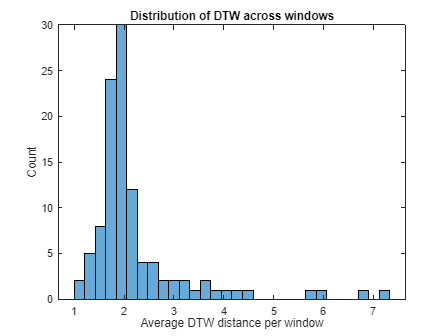

figure;
histogram(avg_dtw_all(~isnan(avg_dtw_all)), 30);
xlabel('Average DTW distance per window');
ylabel('Count');
title('Distribution of DTW across windows');

% Using a percentile-based threshold dynamically filters out the noisiest 
% windows based on the actual distribution of the signal, instead of relying on an arbitrary fixed value.
dtw_valid = avg_dtw_all(~isnan(avg_dtw_all));
median_dtw = median(dtw_valid);
p90_dtw = prctile(dtw_valid, 90);
fprintf('Median DTW: %.3f | 90th Percentile DTW: %.3f\n', median_dtw, p90_dtw);

Median DTW: 1.958 | 90th Percentile DTW: 3.498


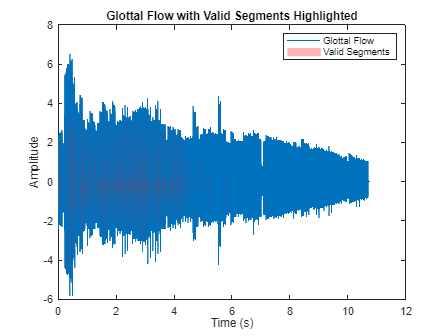

t = (0:length(fG)-1)/fs; 

figure;
plot(t, fG);
xlabel('Time (s)');
ylabel('Amplitude');
title('Glottal Flow with Valid Segments Highlighted');
hold on;

for i = 1:length(accepted_indices)
    idx_start = accepted_indices(i);
    idx_end = idx_start + window_length - 1;
    if idx_end > length(fG)
        continue;
    end
    
    t_segment = t(idx_start:idx_end);
    y_segment = fG(idx_start:idx_end);
    
    fill([t_segment, fliplr(t_segment)], ...
         [y_segment, zeros(size(y_segment))], ...
         'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
end

hold off;
legend('Glottal Flow', 'Valid Segments');

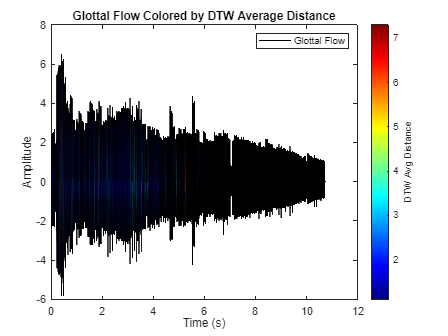

figure;
plot(t, fG, 'k', LineWidth=0.1);
xlabel('Time (s)');
ylabel('Amplitude');
title('Glottal Flow Colored by DTW Average Distance');
hold on;

% Colormap
cmap = jet(256);
dtw_min = min(avg_dtw_all(~isnan(avg_dtw_all)));
dtw_max = max(avg_dtw_all(~isnan(avg_dtw_all)));

for i = 1:num_windows
    idx_start = (i - 1) * window_length + 1;
    idx_end = idx_start + window_length - 1;
    
    if idx_end > length(fG) || isnan(avg_dtw_all(i))
        continue;
    end
    
    
    color_idx = round(1 + (avg_dtw_all(i) - dtw_min) / (dtw_max - dtw_min) * 255);
    color_idx = max(1, min(256, color_idx));
    segment_color = cmap(color_idx, :);
    
    t_segment = t(idx_start:idx_end);
    y_segment = fG(idx_start:idx_end);

    
    fill([t_segment, fliplr(t_segment)], ...
         [y_segment, zeros(size(y_segment))], ...
         segment_color, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
end

colormap(cmap);
colorbar;
clim([dtw_min dtw_max]);
ylabel(colorbar, 'DTW Avg Distance');
legend('Glottal Flow');
hold off;